**Setting**

Doing V0 calculation for each test and gain basic data from calibration process

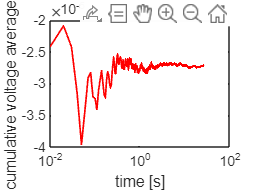

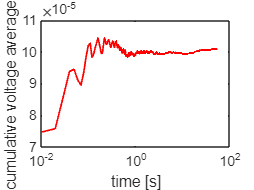

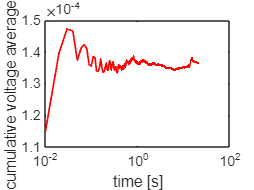

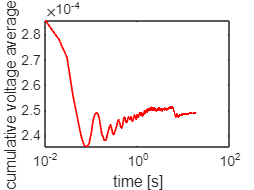

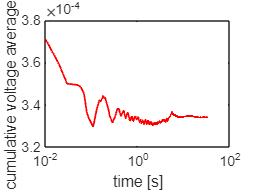

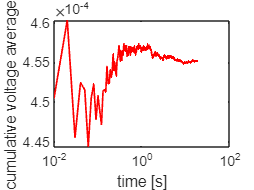

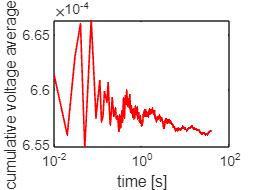

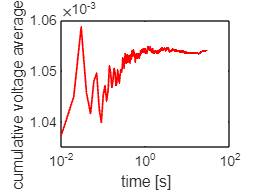

start_point

test_num=16;
time_stable_estime= max(time_vec);

Note that the values of V0 are, in themselves, random. In fact, repetition of the same test produces different values of V0. A formula can be derived, which estimates the limiting mean of the Vo values, say μVo, as a function of the “reference” force value, F*. This can be obtained by linear regression of the (F*-Vo) pairs. The formula will have the following form:

𝝁𝑽𝒐=𝒎𝑭∗+𝒃

Finding out the values of 𝒎 and 𝒃 through a least squares system.

A=[ones(test_num, 1), forces'];
r=voltages';

x_mq=A\r;
b=x_mq(1); m=x_mq(2);

% % check if it makes sense
% y=interp1(forces, voltages, 0:0.0001:1);
% 
% f=@(x) b +x.*m;
% figure();
% plot(0:0.0001:1, y, 'b-', 0:0.0001:1, f(0:0.0001:1), 'r-' );

we would like to find 𝑼 such that, for every 𝑽𝒐, the corresponding force lies within the range 𝑭̃±𝑼. 

A first approach is to set 𝑼 as the maximum absolute difference between 𝑭̃ and 𝑭∗ for all the 16 calibration cases.

f_tilde=@(x) (x-b)./m;
U1=0; 
for ii=1:length(forces)
    if abs(forces(ii)-f_tilde(voltages(ii)))>U1
        U1=abs(forces(ii)-f_tilde(voltages(ii)));
    end
end
U1

U1 = 0.0134

For a perfect Gaussian PDF, 95% of the readings falls in the range 𝝁±𝟐𝝈. According to the theory of linear regression, we can estimate 𝑼 at a 95% confidence as

𝟐𝒔̅𝑭̃  where sf is the campioanary variance  

vec=(f_tilde(voltages)-forces).^2;
U2=2*sqrt((1./(test_num-2))*sum(vec));
U2

U2 = 0.0112